close all; clear all; clc

## Lab 6

*Name: Joshua Yap*

*Lab Partner: Dane Thorn*

    This week's lab explores confidence intervals using a simulated background and injected signals. The background to be simulated is Poisson distributed with a mean of 100.

### Problem 1

We randomly generate Poisson distributed data and plot it in a histogram.

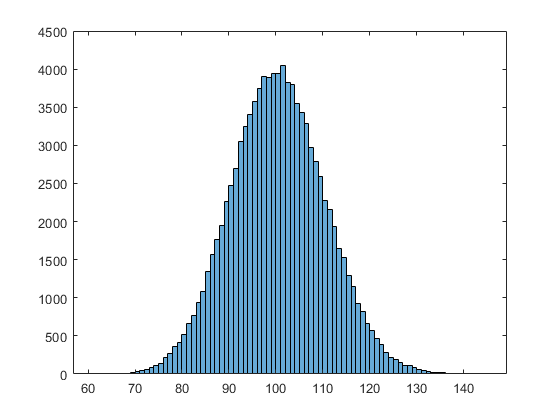

rng('default');
rng(2);
lambda = 100;
background = poissrnd(lambda,[1,100000]);
histogram(background)

When we normalize the histogram and fit it to a Poisson distribution, we can superimpose the resulting pdf on the normalized histogram.

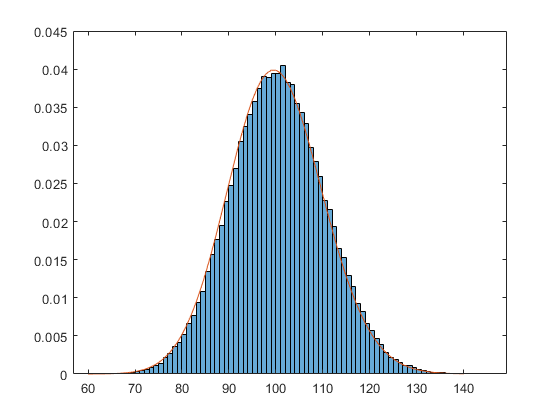

x = 60:140;
bgfit = poissfit(background);
histogram(background,'Normalization','pdf')
hold on
plot(x,poisspdf(x,bgfit));
hold off

In this experiment, we are going to assume that a more signal-like observation gives us a higher value. We are interested in the 5$\sigma$ threshold of the background distribution, so we integrate the upper tail.

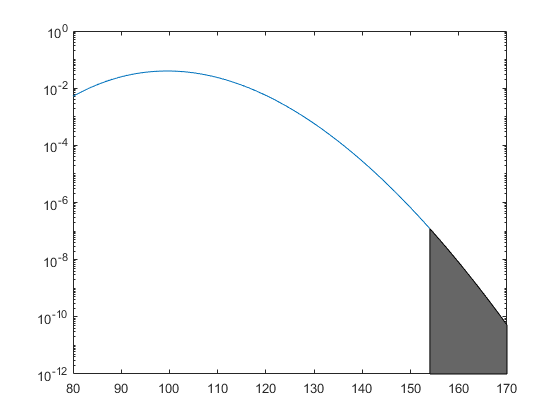

a = normcdf(5,'upper');
fivesig = poissinv(1-a,lambda);
plot(80:170,poisspdf(80:170,bgfit))
hold on
area(fivesig:170,poisspdf(fivesig:170,bgfit),'FaceColor',[0.4 0.4 0.4])
set(gca,'YScale','log')
hold off

The 5$\sigma$ threshold is found to be 154, so any observation of 154 or greater (represented by the shaded region) can be claimed to be a discovery.

### Problem 2

Now we inject a simulated signal of value corresponding to a probability of 8$\sigma$ on our Poisson distribution.

b = normcdf(8,'upper');
eightsig = poissinv(1-b,lambda);

This value is found to be 190. To inject the signal, we add this value to random values already in our background data. This generates points centered around 290.

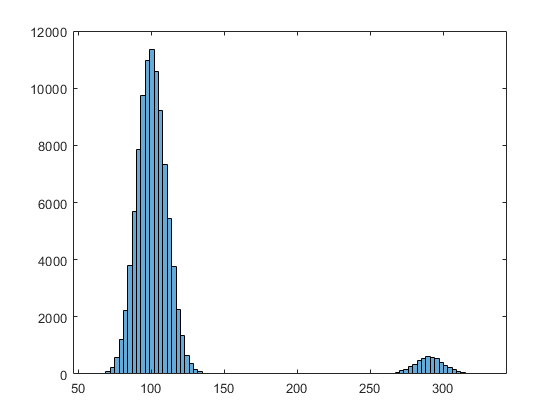

strength = eightsig;
sigcount = 5000;
signal = [strength*ones(1,sigcount) zeros(1,length(background)-sigcount)];
inject = signal+background;
histogram(inject)

We have chosen 1 out of every 20 background data points to inject a signal into. The histogram features two humps - one centered on the mean (100) and one centered on the signal value (290). This makes sense because we have simply shifted some values originally centered on 100 by 190.

It is interesting to note that although we injected a constant value of 190 to 5000 data points, we end up with a distribution around 290 as opposed to something that looks like a delta-function. This happens because the values we are injecting the signal to have a distribution. We now want to analyze how this injected signal is distributed.

Intuitively, we conjecture that the signal should be Poisson distributed since the background data it was injected to is Poisson distributed. We check this by fitting a Poisson pdf to the signal histogram.

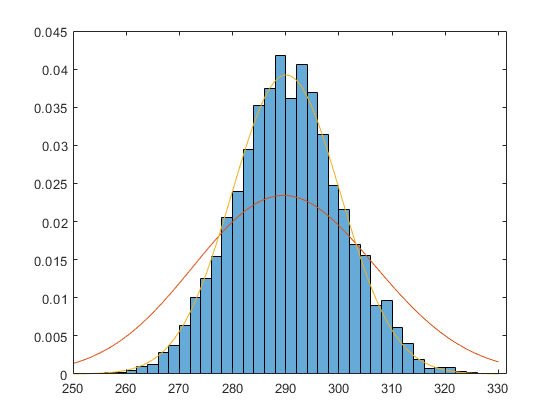

figure
histogram(inject(1:sigcount),'Normalization','pdf')
hold on
sigfit = poissfit(inject(1:sigcount));
plot(250:330,poisspdf(250:330,sigfit))
[mu2,sig2] = normfit(inject(1:sigcount));
plot(250:330,normpdf(250:330,mu2,sig2))
hold off

The Poisson fit with parameter $\lambda$ = 290 does not fit the histogram that well. Interestingly, a Gaussian fits the data better. This could be the case because the Gaussian has 2 degrees of freedom (mean and standard deviation) while the Poisson only has 1 (mean). The Gaussian is therefore a better approximation of the signal distribution than a Poisson with mean 290. However, we also wanted to see if we could shift the x-axis in order to fit the original Poisson distribution with mean 100 to the signal distribution. This is plotted below.

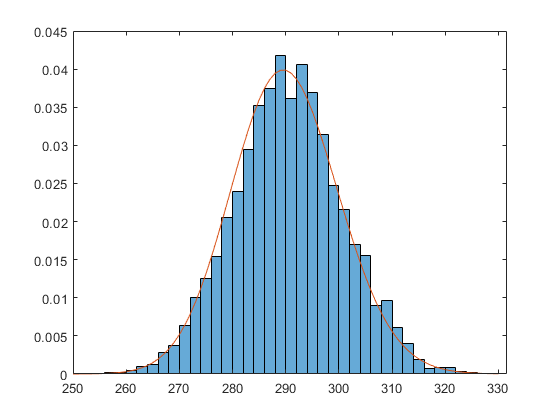

figure
histogram(inject(1:sigcount),'Normalization','pdf')
hold on
plot(250:330,poisspdf(x,bgfit))
hold off

This also fits the data well, and might be the best fit of the data given the background data was originally Poisson distributed. We compare the fits on the log plot below.

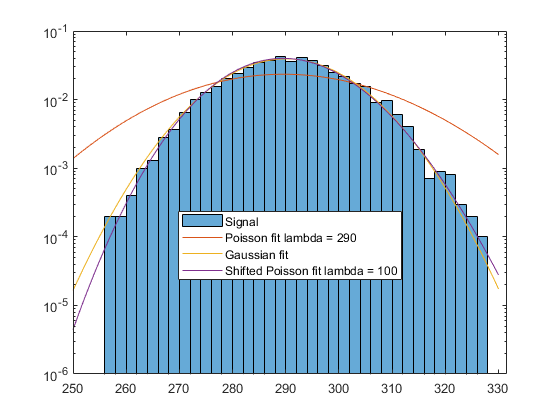

figure
histogram(inject(1:sigcount),'Normalization','pdf')
hold on
plot(250:330,poisspdf(250:330,sigfit))
plot(250:330,normpdf(250:330,mu2,sig2))
plot(250:330,poisspdf(x,bgfit))
legend('Signal','Poisson fit lambda = 290','Gaussian fit', ...
    'Shifted Poisson fit lambda = 100','Location','best')
set(gca,'YScale','log')
hold off

We conclude that the shifted Poisson fit is the best fit to the data and accounts for the larger upper tail, but the Gaussian is a good approximation.

Our observed signal has a mean of 290.0716, which is much larger than the true injected signal of 190. Since the observed signal is higher than the injected signal, it is biased. The observed signal is much more likely to be higher than the injected signal.

Given the conclusions about the shape of the histogram, since it has a slightly larger upper tail, we are more likely to observe signals larger than the true injected signal. However, since the Gaussian, which is symmetric, is a good approximation of the signal distribution, the asymmetry can be considered negligible and the observed value is approximately equally likely to be stronger or weaker than the true injected signal.

### Problem 3

 Now instead of injecting a signal of a single value, we simulate a range of signal strengths to inject. This range goes from 0 to 1000. We want to find out how the distribution of observed signal strength changes with different injected signals.

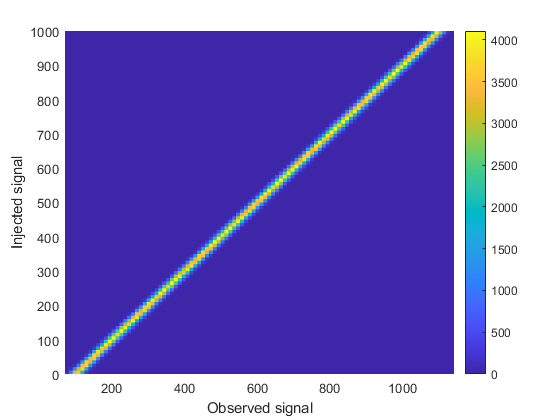

size3 = 1000;
rng('default');
rng(2);
background3 = poissrnd(lambda,[size3,size3]);
% histogram(background)
sigstrength = 0:size3-1;
[x_sig signal3] = meshgrid(sigstrength);
obssignal3 = background3+signal3;

figure
histogram2(obssignal3,signal3,100,'DisplayStyle','tile','ShowEmptyBins','on')
ylabel('Injected signal')
xlabel('Observed signal')
colorbar();

This 2D histogram shows the observed signal against the injected signal, where a lighter color represents more counts. We can check that this histogram corresponds to our 1D histogram when we choose to inject a single signal of 190.

index = 191;
signal3(index)

ans = 190

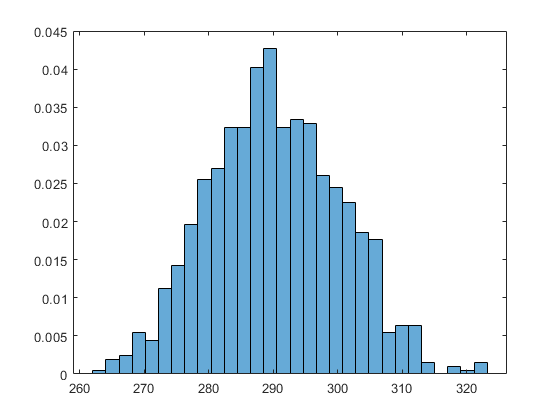

figure
histogram(obssignal3(index,:),30,'Normalization','pdf')

This histogram is not the same as our histogram in problem 2 because we have a different set of randomly generated variables, but it exhbits the same properties of having a Gaussian shape and is centered around 290.

Now we want to reverse the problem and look at a vertical slice of the histogram, ie. for a given observed signal, what is the range of true injected signals that could have given me that observed signal?

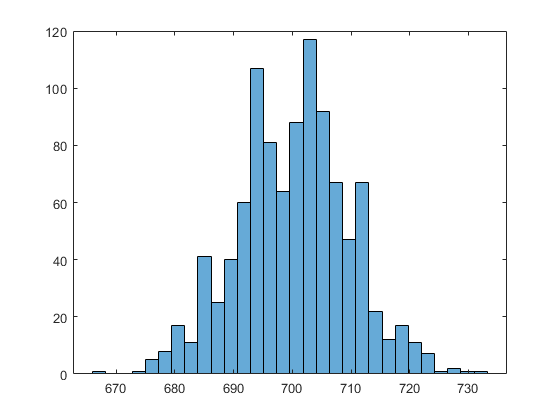

h3 =   Histogram with properties:

             Data: [1013×1 double]
           Values: [1 0 0 1 5 8 17 11 41 25 40 60 107 81 64 88 117 92 67 47 67 22 12 17 11 7 1 2 1 1]
          NumBins: 30
         BinEdges: [1×31 double]
         BinWidth: 2.2400
        BinLimits: [666 733.2000]
    Normalization: 'count'
        FaceColor: 'auto'
        EdgeColor: [0 0 0]

  Show all properties


observation = 800;
inject3 = signal3(obssignal3-observation==0);
h3 = histogram(inject3,30)

For an observed signal of 800, there is a range of injected signals from 670 to 730 that could have given us this observed signal. We are interested in finding the 1$\sigma$ uncertainty on the true signal value, so we first find the mean of the histogram and add up probabilities of bins around it until it sums to the probability corresponding to 1$\sigma$.

c = 0.5-normcdf(1,'upper');
mu3 = mean(inject3);
% Compute normalized pdf bins
% Sum bins from mean upward and downward to get 1 sigma range


### Problem 4

Now we pick an observed signal in the 1$\sigma$ range. 

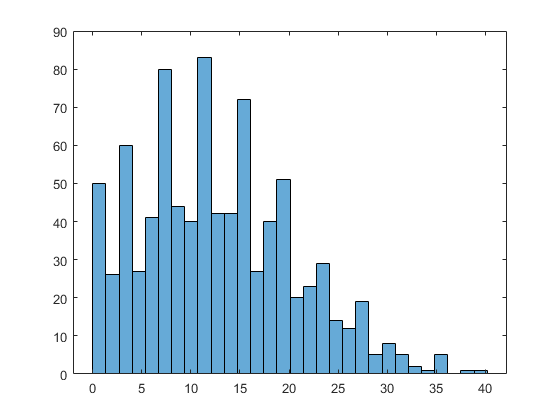

h3 =   Histogram with properties:

             Data: [870×1 double]
           Values: [50 26 60 27 41 80 44 40 83 42 42 72 27 40 51 20 23 29 14 12 19 5 8 5 2 1 5 0 1 1]
          NumBins: 30
         BinEdges: [1×31 double]
         BinWidth: 1.3400
        BinLimits: [0 40.2000]
    Normalization: 'count'
        FaceColor: 'auto'
        EdgeColor: [0 0 0]

  Show all properties


d = normcdf(1,'upper');
onesig = poissinv(1-d,lambda);
observation4 = 110;
inject4 = signal3(obssignal3-observation4==0);
h3 = histogram(inject4,30)

The range of true signals the observed signal of 110 could have come from ranges from 0 to 40. This is significant because that means that a non-signal could have resulted in an observation that looks like a signal.

Now we calculate the 95% confidence upper bound for the true signal, meaning if I observe a candidate signal of 110, then the true value of the signal would be less than *X *95% of the time.

% Integrate from 0 up until area = 0.95
sorted = sort(inject4);
ans = sorted(round(0.95*length(sorted)))

ans = 27

We get an upper bound *X* value of 27.